## 13.6 Applications

### 13.6.1 Fiducial Markers

Se carga y se muestra la imagen original

scene = imread("aprilTag36h11.jpg");

Vista de la imágen

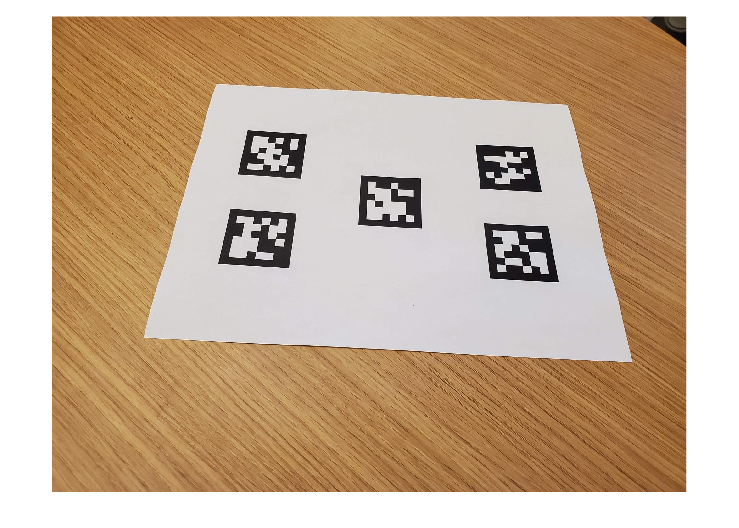

imshow(scene);

Se cargan las propiedades de la cámara

 - Parámetros intrínsecos de la cámara desde un archivo `.mat`

data = load("camIntrinsicsAprilTag.mat");
intrinsics = data.intrinsics;
intrinsics

intrinsics =   cameraIntrinsics with properties:

             FocalLength: [2.7217e+03 2.7247e+03]
          PrincipalPoint: [1.4471e+03 1.1344e+03]
               ImageSize: [1512 2016]
        RadialDistortion: [0.1084 -0.1298]
    TangentialDistortion: [0 0]
                    Skew: 0
                       K: [3×3 double]


Corrige la distorsión de la imagen 

Eliminación de la distorsión de lente de la imagen usando los parámetros intrínsecos

scene = undistortImage(scene,intrinsics,OutputView="same");

Deteción de los marcadores AprilTag

- El algoritmo `readAprilTag` detecta los marcadores de** tipo **`tag36h11` en la imagen.

- `id`: Identificadores únicos de los marcadores detectados.

- `loc`: Coordenadas de las esquinas de los marcadores en la imagen.

- `pose`: Posición y orientación de los marcadores en el espacio 3D.

tagSize = 0.04; % in meters
[id,loc,pose] = readAprilTag(scene,"tag36h11",intrinsics,tagSize);

Definición de los puntos para dibujar los ejes

Los puntos en el espacio 3D para dibujar los ejes de referencia en la posición de cada marcador:

- Punto de origen `(0, 0, 0)`.

- Extremos de los ejes X, Y y Z a una distancia proporcional al tamaño del marcador.

worldPoints = [0 0 0; tagSize/2 0 0;...  % define axes points to draw
  0 tagSize/2 0; 0 0 tagSize/2];

**Se dibujan los ejes y las etiquetas en la imagen para los marcadores:**

- Convierte las coordenadas 3D `worldPoints` a puntos de imagen `imagePoints` usando su pose y los parámetros de la cámara.

- Se dibujan líneas representando los **ejes X, Y y Z con colores rojo, verde y azul** respectivamente.

- Se inserta el identificador del marcador cerca de su posición detectada.

for i = 1:length(pose)
  imagePoints = world2img(worldPoints,pose(i),intrinsics);
  scene = insertShape(scene,"Line",[imagePoints(1,:) imagePoints(2,:); ...
    imagePoints(1,:) imagePoints(3,:); imagePoints(1,:) imagePoints(4,:)], ...
    Color=["red","green","blue"],LineWidth=12);
  scene = insertText(scene,loc(1,:,i),id(i),BoxOpacity=1,FontSize=28);
end

Imágen de resultado final

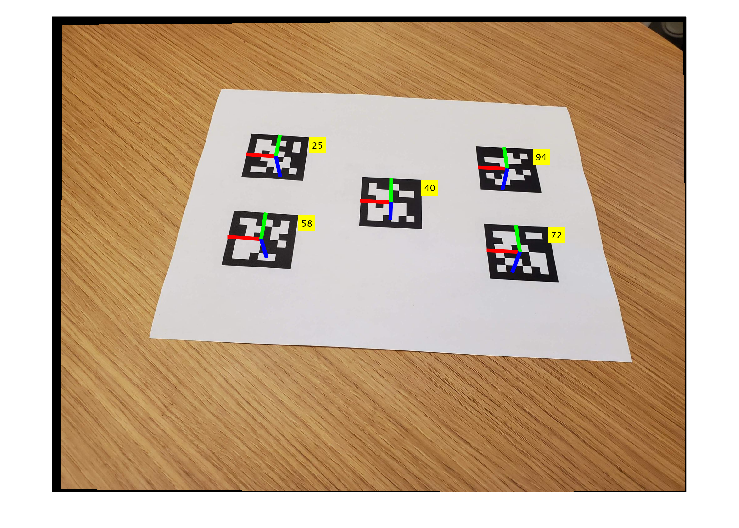

imshow(scene)